**1. Création des données de test**

maxPWM = 1.00; % maximum duty cycle
incrPWM = 0.05; % PWM increment
PWMcmdRaw = (-maxPWM:incrPWM:maxPWM); % column vector of duty cycles from -1 to 1

**2. Créer et initialiser des objets de périphérique**

clear a dcm carrier enc %supprime les objetse xistants
a = arduino;
carrier = addon(a, 'Arduino/MKRMotorCarrier');
dcm = dcmotor(carrier, 3);
enc = rotaryEncoder(carrier, 1);
resetCount(enc);

**3-5. Appeler la fonction de caractérisation motrice**

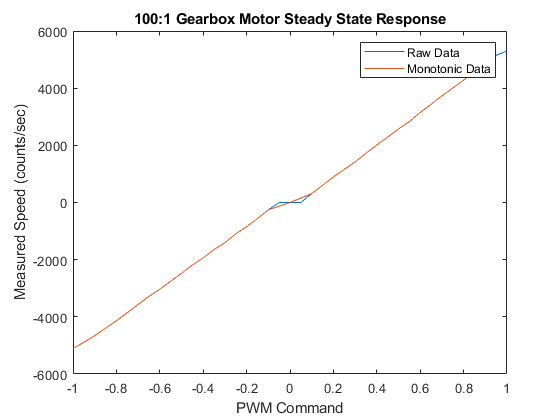

[PWMcmdMono,speedMono] = myMotorFunction(PWMcmdRaw,dcm,enc,'motorResponse');